clc
clear 
close all


## Reading the ASR file

% skips reading file upto 21 line
 skipLine = 21;
[asrData,asrHeader ] = dat_file_reader('17071530_cdt.txt',skipLine);

% converting in to date of Year
 dateInString = strcat(string(asrData.asr_month) + '/' + string(asrData.asr_day) + '/' + string(asrData.asr_year));
 
% using the function date2doy to get dateofYear
% char is used because the datenum can't work with the sting class type.
[asr_doy,~,~] = date2doy(datenum(char(dateInString)));

% Astronomical distance based on the chander table for the given doy 196 is 
%https://ac.els-cdn.com/S0034425709000169/1-s2.0-S0034425709000169-main.pdf?_tid=446cb217-94c9-40b6-a4f3-b90de3f319c4&acdnat=1538148381_c3189ee5f772c9c039f0ba29ab140fc5
astDistance = 1.01646;

% squaring the astronomical Distance
sqAstDistance = astDistance .^2;


## Calculating the Solar Zenith angle

for dataRead = 1:size(asrData,1)
    %calculating the solar zenith angle using the time.
    %creating time structure
    time.year = asrData.asr_year(dataRead);
    time.month = asrData.asr_month(dataRead);
    time.day = asrData.asr_day(dataRead);
    time.hour = asrData.asr_hour(dataRead);
    time.min = asrData.asr_minute(dataRead);
    time.sec = asrData.asr_second(dataRead);
    time.UTC = -5;  ... confusion in this line
    
    % creating the location structure
    % the information is generated from the google maps
    location.latitude = 44.291;
    location.longitude = -96.765;
    location.altitude = 505;
    
    % calling the function sun_position
    [sunInfo] = sun_position(time,location);
    asr_sunZenith(:,dataRead) = sunInfo.zenith;
    asr_sunAzimuth(:,dataRead) = sunInfo.azimuth;
end 
 timeValue = asrData.asr_hour + asrData.asr_minute/60 +asrData.asr_second/360;

**Calculating the optical Depth **

opticalDepth = ones(size(asrData,1),1) ./ cosd(asr_sunZenith')

opticalDepth =     5.1084
    5.0345
    4.9638
    4.8939
    4.8248
    4.7598
    4.6954
    4.6317
    4.5716
    4.5112


## Plotting the Solar Zenith angle and Solar azimuth angle

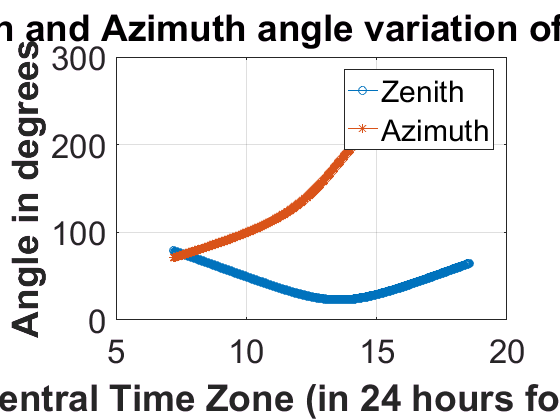

figure 
plot(timeValue,asr_sunZenith,'LineStyle','-','Marker','o');
hold on
plot(timeValue,asr_sunAzimuth,'Marker','*');
hold on 
xlabel('Central Time Zone (in 24 hours format)','FontWeight','bold');
ylabel('Angle in degrees','FontWeight','bold');
legend('Zenith','Azimuth')
title (' Solar Zenith and Azimuth angle variation of ASR with time ')
ax = gca;
ax.FontSize  = 25;
grid on

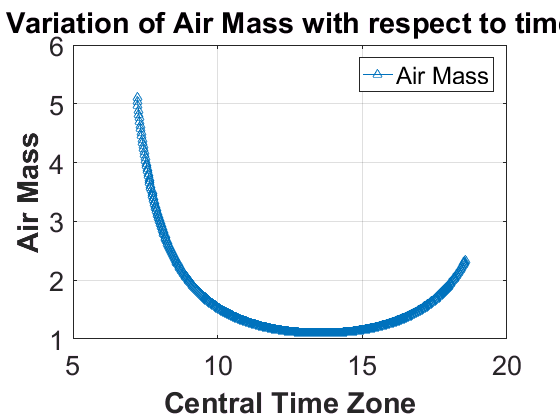


figure 
plot(timeValue, opticalDepth,'Marker','^');
xlabel('Central Time Zone','FontWeight','bold');
ylabel('Air Mass','FontWeight','bold')
title('Variation of Air Mass with respect to time')
legend('Air Mass')
ax = gca;
ax.FontSize  = 20;
grid on

## Section Deals with the data preparation for the plotting

wavelengthColRange  = [12 : 19,21];
wavelengthName = {'380nm','400','440nm','520nm','610nm','670nm','780nm','870nm','1030nm'};
wavelength = [380,400,440,520,610,670,780,870,1030];


$$ln\left(V_{\lambda \text{ }} ∗D^2 \right)$$


rows = 25:31;
asrData(rows,:) = [];
opticalDepth(rows,:) = [];

% multipying the bands output with the astronomical distance and taking the log

for band = wavelengthColRange
    % curly brackes has to be used to extract data for multiplication
    bandSel = asrData{:,band};
    ymultiple =  sqAstDistance * bandSel;
    %taking the natural logarith of the  ymultiple
    logResponse(:,band-11) = log(ymultiple);
end
logResponse(:,9) = [];


## Filtering the data based on the Infinte value


% searching for the infinite value in the data
[infinteValueRow,~] =  find(logResponse == Inf | logResponse == -Inf);

% removing the infinite value from both the optical depth and Y response
logResponse(infinteValueRow,:) = [];
opticalDepth(infinteValueRow,:) = [];

% copying the asrData to another variable and removing the variable 
cop_asr_data = asrData;
cop_asr_data(infinteValueRow,:) = [];

## Plotting the Optical Depth against log Response

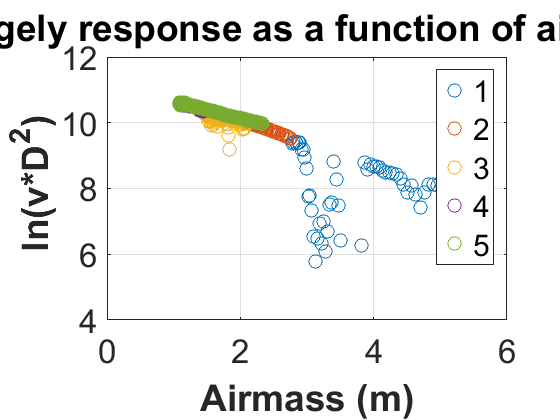

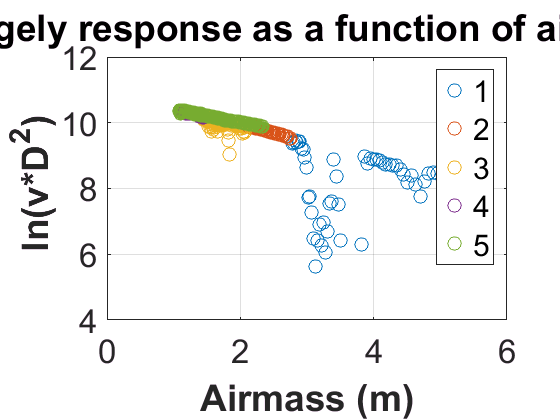

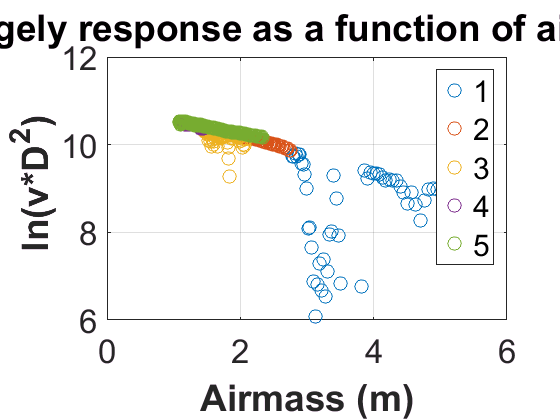

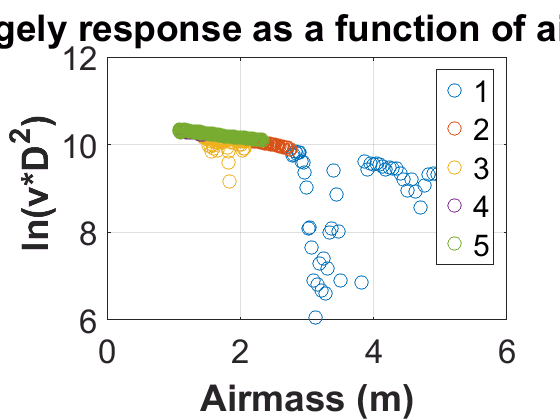

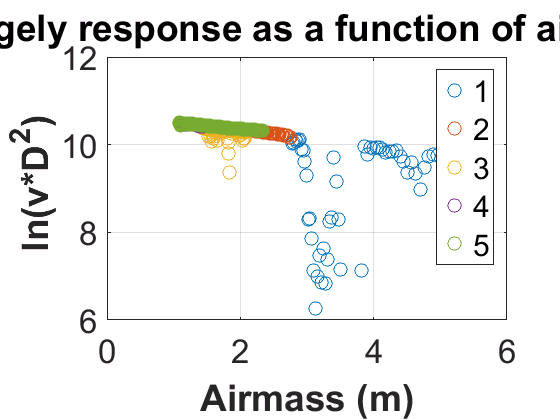

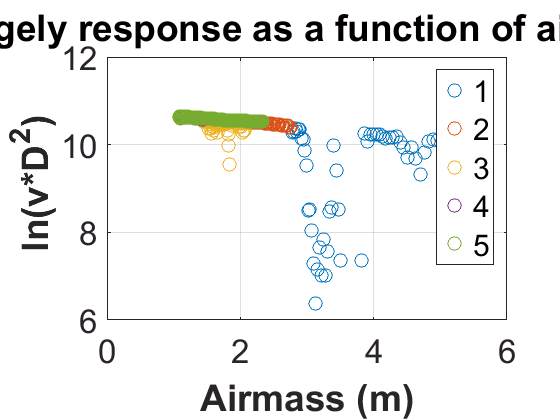

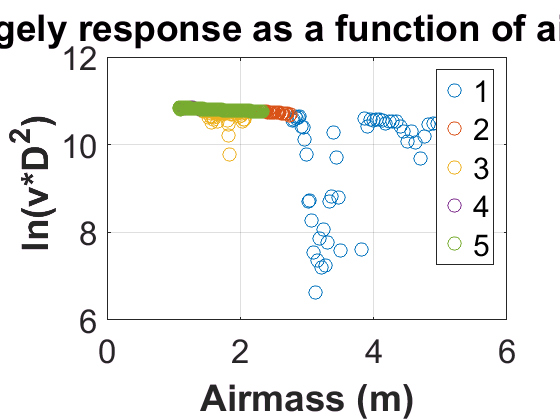

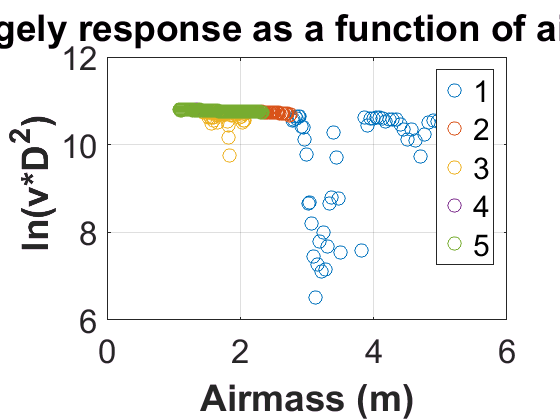



for band = 1: length(wavelengthName)
    figure
    % random  error till 8:6:5 am
    plot(opticalDepth(1:51),logResponse(1:51,band),'Marker','o','LineStyle','None','markers',10)
    hold on
    % till 1:40:5  PM til angle is decreasing
    plot(opticalDepth(52:92),logResponse(52:92,band),'Marker','o','LineStyle','None','markers',10)
    hold on 
    plot(opticalDepth(93:178),logResponse(93:178,band),'Marker','o','LineStyle','None','markers',10)
    hold on 
    plot(opticalDepth(179:382),logResponse(179:382,band),'Marker','o','LineStyle','None','markers',10)
    hold on 
%     plot(opticalDepth(48:382),logResponse(48:382,band),'Marker','o','LineStyle','None')
%     hold on 
    % 1:40:5angle start increasing
    plot(opticalDepth(383:end),logResponse(383:end,band),'Marker','o','LineStyle','None','markers',10)
    xlabel('Airmass (m)','FontWeight','bold');
    ylabel(' ln(v*D^2)','FontWeight','bold');
    title('Langely response as a function of air mass')
    legend('1','2','3','4','5')
    ax = gca;
    ax.FontSize = 25;
    hold on
    grid on
end

## working on three blocks of data

subset(1).a = 1:57; % data till 8:6:5
subset(2).a = 58:98;
subset(3).a = 99:182

subset =   1×3 struct array with fields:

    a


subset(4).a = 183:382;
subset(5).a = 383:675;

% subset(1).a = 1:11;
% subset(2).a = 12-22;
% subset(3).a = 23-50;
% subset(4).a = 51-92;
% subset(5).a = 93-189;
% subset(6).a = 190-388;
% subset(7).a = 389-675;



## Fitting  a line on the value

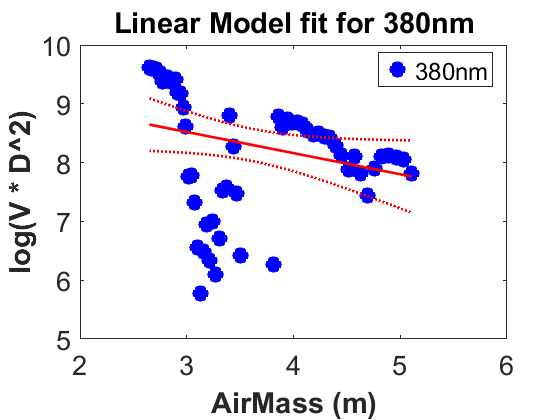

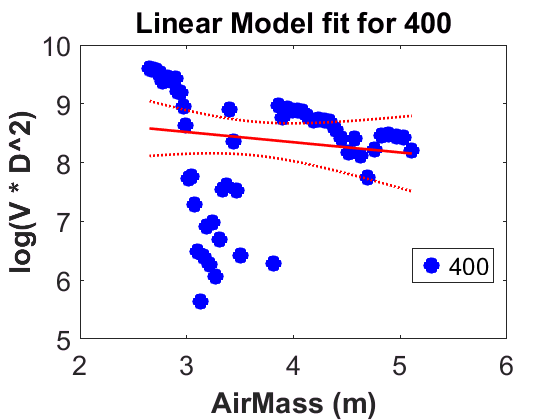

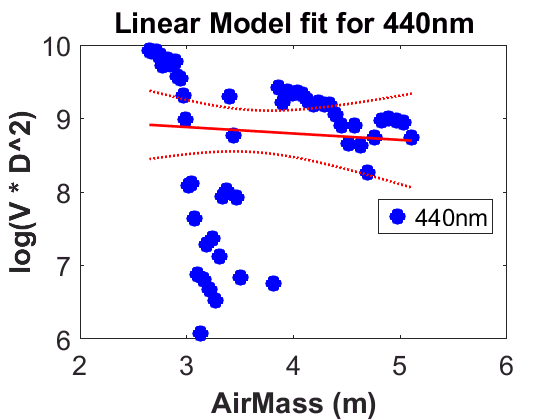

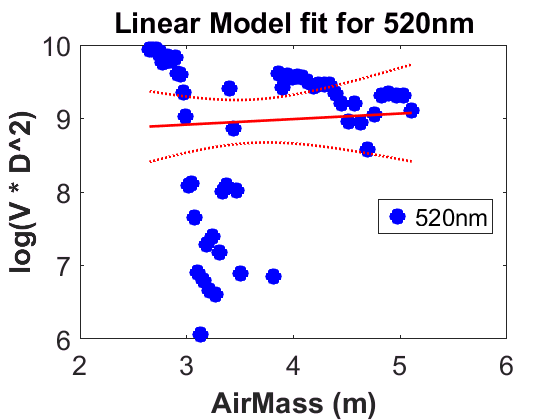

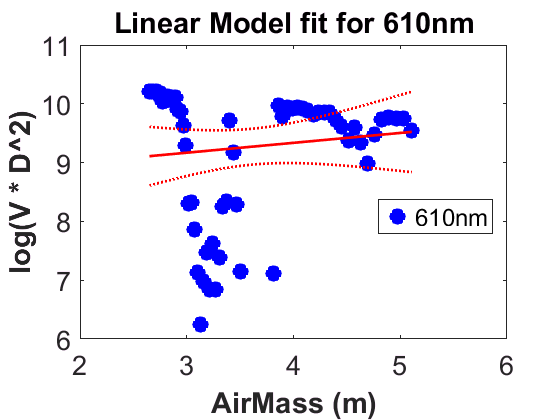

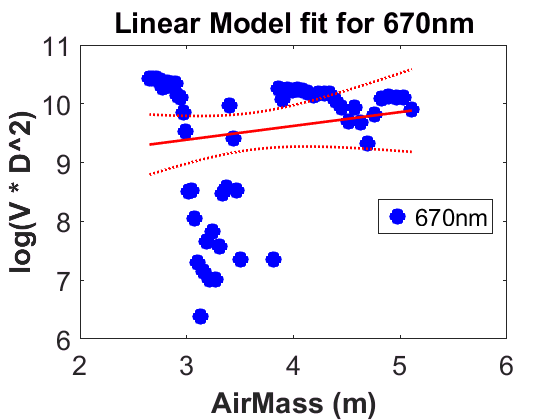

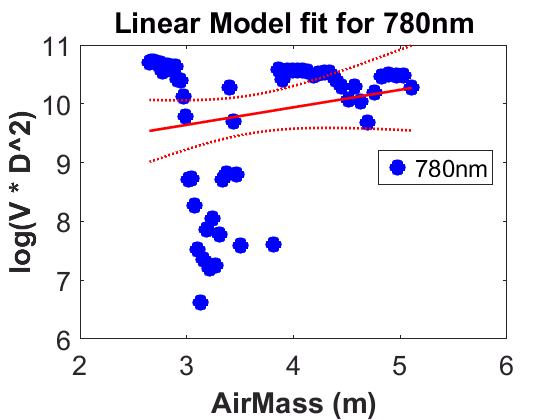

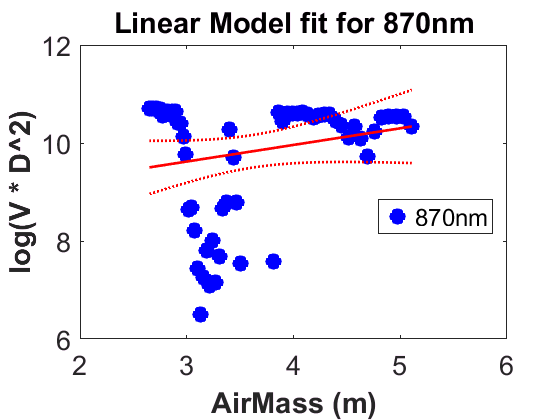


for i = 1:5
    logResponse1 = logResponse(subset(i).a,:);
    opticalDepth1 = opticalDepth(subset(i).a);
%        logResponse1 = logResponse
%        opticalDepth1 = opticalDepth
    summaryCell = cell(8,6);
    % predictedReflectance = zeros(size(solarFiltered,1),7);
    % fitting regression line for the each band 
    cookDisOut = zeros(100,1);
    betahat = zeros(8,7);
    for band =  1:length(wavelengthName) 
        % Entering all the data into the table for the linear fit
        lineFitTable = table(logResponse1(:,band),opticalDepth1);
        lineFitTable.Properties.VariableNames = {'yResponse','xPredictor'};
        model  = fitlm(lineFitTable,'yResponse ~ xPredictor','Robust','on');
        % coefficients of the linear fit 
        [coeffrow ,~] = size(model.Coefficients.Estimate);
        betahat(1:coeffrow,band) = model.Coefficients.Estimate;
        
      
        figure 
        h = plot(model,'Marker','o','MarkerSize', 10, 'MarkerFaceColor','b');
        set(h,'LineWidth',2)
        titleText = strcat('Linear Model fit for',{' '}, wavelengthName{band});
        title(titleText)
        xlabel('AirMass (m)','FontWeight','bold');
        ylabel('log(V * D^2)','FontWeight','bold');
        legend(wavelengthName{band});
        ax = gca;
        ax.FontSize = 20;
        
%         leveragethreshold = 2*1/size(lineFitTable,1);
%         highLeveragePoints = find(leveragethreshold > model.Diagnostics.Leverage);
        
        % cooks distance  to check if any points are influencing the line more
        % than the otheres
        % Cookd Distance greater than 0.5 are points needed to be investigated
        % Cookd Distance greater that 1 are potential outliers in the data
%     %     figure
%     %     plotDiagnostics(model,'cookd')
%         cookDisOut = [find((model.Diagnostics.CooksDistance)> 5*mean(model.Diagnostics.CooksDistance));cookDisOut];
       
    %     figure
    %     bar(model.Diagnostics.CooksDistance)
       
        
%         % Displaying the model fit statistics 
%         disp(strcat('#######################################################'));
%         textValue = strcat('Model ' , num2str(band), wavelengthName{band}); 
%         warning(textValue);
%         disp(model)
%         
%         %{
%         H0: The relationship assumed in the model is reasonable, i.e., there is no lack of fit.
%         HA: The relationship assumed in the model is not reasonable, i.e., there is lack of fit.
%         %}
%         
%         % analysis of variance 
%         anova(model,'summary')
%         
%         disp(strcat('#######################################################'));
        
        summaryCell(band,:) = {wavelengthName{band}; model.Rsquared.Ordinary*100; ...
            model.Rsquared.Adjusted*100; model.RMSE*100; model.Coefficients.Estimate(1); ...
            model.Coefficients.Estimate(2)}; 
        
    end
    summaryTable(i).a = cell2table(summaryCell);
    clear summaryCell
    summaryTable(i).a.Properties.VariableNames = {'Band', 'Rsquared', ...
        'AdjustedRsquared', 'RMSE','Intercept','Slope'};
end

## calculating  the calibration constant

for i = 1:5
    calibration_Contant(:,i) = exp(summaryTable(i).a.Intercept);
end

Calculating the Rayleigh scattering

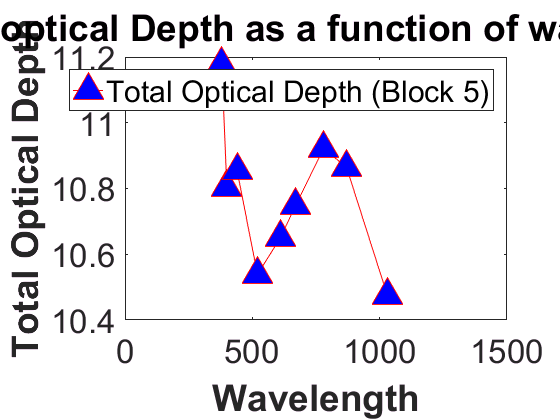

ray.a = 0.008569;
ray.b = 0.0113;
ray.c = 0.00013;
% https://www.timeanddate.com/weather/usa/brookings/historic?month=7&year=2017
pValue = 30.17;
%https://en.wikipedia.org/wiki/Atmospheric_pressure
pAbsolute = 29.921;


for wave = 1:length(wavelength)
    rayLeighValue(wave) = (ray.a*(wavelength(wave)^(-4)) * (1 + ray.b*(wavelength(wave)^(-2) + ray.c*(wavelength(wave)^(-4)))))*pValue/pAbsolute;
end

figure 
plot(wavelength,summaryTable(5).a.Intercept,'Marker','^','Color','Red','markers',20,'MarkerFaceColor','b')
xlabel('Wavelength','FontWeight','bold')
ylabel('Total Optical Depth', 'FontWeight','bold');
title('Total optical Depth as a function of wavelength');
ax = gca;
ax.FontSize = 25;
legend('Total Optical Depth (Block 5)');

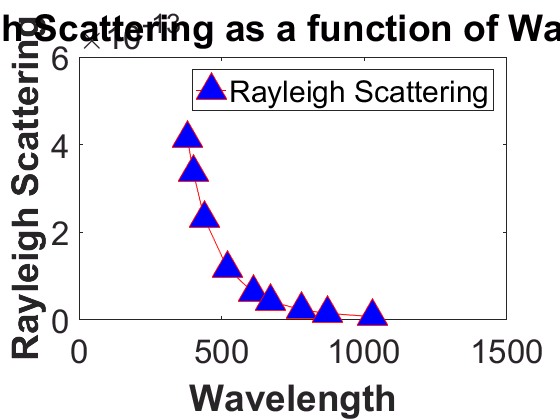



figure 
plot(wavelength,rayLeighValue,'Marker','^','Color','Red','markers',20,'MarkerFaceColor','b')
xlabel('Wavelength','FontWeight','bold')
ylabel('Rayleigh Scattering', 'FontWeight','bold');
title('Rayleigh Scattering as a function of Wavelength');
ax = gca;
ax.FontSize = 25;
legend('Rayleigh Scattering');

## calculating the aerosol value

for i = 1:5
    summaryTable(i).a.Tau_aerosol = abs(summaryTable(i).a.Slope) - transpose(rayLeighValue);
end



## plotting the each band to extract the information at 936nm

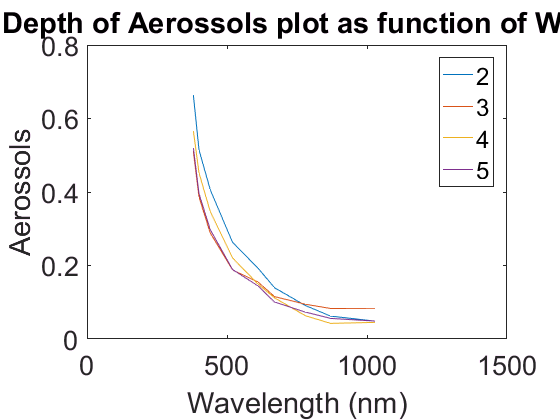

figure
for i = 2:5 
     plot(wavelength,summaryTable(i).a.Tau_aerosol)
     xlabel('Wavelength (nm)');
     ylabel('Aerossols');
     title('Optical Depth of Aerossols plot as function of Wavelength');
     hold on
     legend('2','3','4','5');
     ax = gca;
     ax.FontSize = 20;
end

## Fitting for each equation

fitResult =      General model:
     fitResult(x) = b*x^(-a)
     Coefficients (with 95% confidence bounds):
       a =       2.726  (2.406, 3.045)
       b =   6.765e+06  (-6.281e+06, 1.981e+07)

gof =            sse: 0.0029
       rsquare: 0.9922
           dfe: 7
    adjrsquare: 0.9911
          rmse: 0.0205


x =    1.0e+06 *

    0.0000    6.7648


fitResult =      General model:
     fitResult(x) = b*x^(-a)
     Coefficients (with 95% confidence bounds):
       a =       2.423  (1.834, 3.012)
       b =   8.262e+05  (-2.121e+06, 3.773e+06)

gof =            sse: 0.0073
       rsquare: 0.9607
           dfe: 7
    adjrsquare: 0.9551
          rmse: 0.0322


x =    1.0e+05 *

    0.0000    8.2616


fitResult =      General model:
     fitResult(x) = b*x^(-a)
     Coefficients (with 95% confidence bounds):
       a =       2.881  (2.62, 3.143)
       b =    1.48e+07  (-8.576e+06, 3.818e+07)

gof =            sse: 0.0013
       rsquare: 0.9956
           dfe: 7
    adjrsquare: 0.9950
          rmse: 0.0136


x =    1.0e+07 *

    0.0000    1.4801


fitResult =      General model:
     fitResult(x) = b*x^(-a)
     Coefficients (with 95% confidence bounds):
       a =       2.806  (2.352, 3.261)
       b =   8.425e+06  (-1.469e+07, 3.154e+07)

gof =            sse: 0.0033
       rsquare: 0.9852
           dfe: 7
    adjrsquare: 0.9831
          rmse: 0.0217


x =    1.0e+06 *

    0.0000    8.4252


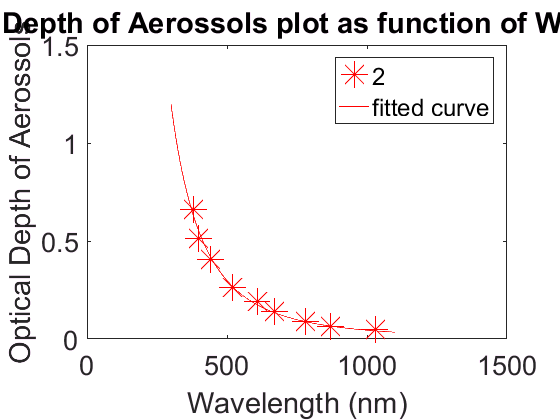

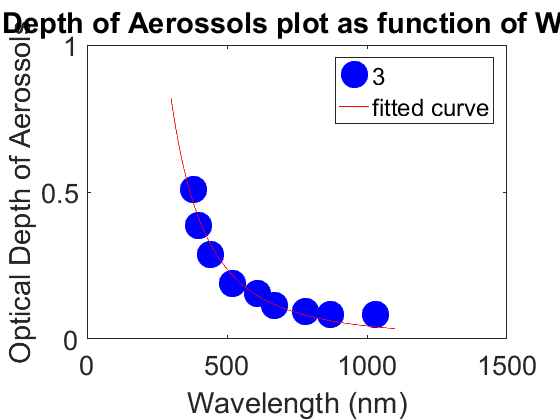

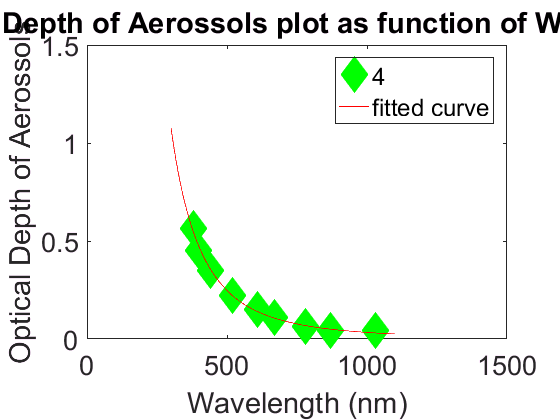

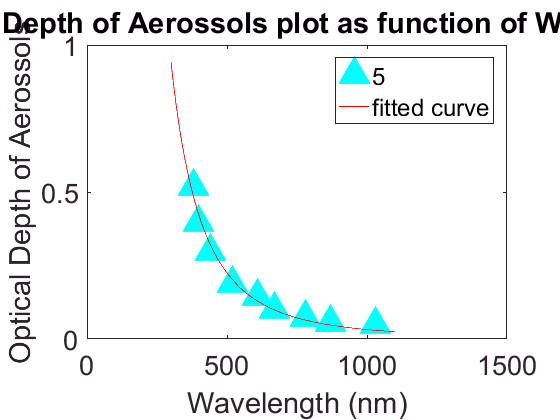

ft = fittype( 'b*x^(-a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';

marker = {'<','*','o','d','^'};
color = {'y','r','b','g','c'};


for i = 2:5
    [fitResult,gof] = fit(transpose(wavelength),summaryTable(i).a.Tau_aerosol,ft,opts)
    x = coeffvalues(fitResult)
    value_beta(i) = x(2);
    aer_940_nm(i) = feval(fitResult,940);
    aer_550_nm(i) = feval(fitResult,550);
   figure
    plot(wavelength,summaryTable(i).a.Tau_aerosol,'LineStyle','None','Marker',marker{i},'Color',color{i},'MarkerFaceColor',color{i},'MarkerSize',20);
    legend(num2str(i));
    hold on
    plot(fitResult)
    ax = gca;
    ax.FontSize = 20;
    title('Optical Depth of Aerossols plot as function of Wavelength');
    xlabel('Wavelength (nm)');
    ylabel('Optical Depth of Aerossols');
    hold on
end

## calculating the visibility of the data


$$\beta \text{ }=0\ldotp 613∗e^{−\frac{VIS}{15}}$$


for i = 2:5
    VIS_value(i) = log(0.613/value_beta(i))*15;
end



## Performing the same processing for the water content using the 940 nm data


$$ln\left(V_{\lambda } ∗D^2 \right)+\text{ }m∗\tau_{936} =ln\left(V_{936} \right)−a∗W^b ∗m^c$$


a = 0.6548;
b = 0.574;
c = 0.574; 

logResponse_940 = log(sqAstDistance * asrData.asr_940nm);
logResponse_940(infinteValueRow) = [];
[infiniteValueRow,~] = find(logResponse_940 == -Inf | logResponse_940 == Inf)


infiniteValueRow =

  0×1 empty double column vector



logResponse_940(infiniteValueRow) = []

logResponse_940 =     7.0991
    7.3372
    7.3532
    7.3953
    7.3806
    7.1051
    6.5951
    6.9968
    7.2603
    7.0466


opticalDepth(infiniteValueRow) = []

opticalDepth =     5.1084
    5.0345
    4.9638
    4.8939
    4.8248
    4.7598
    4.6954
    4.6317
    4.5716
    4.5112


#######################################################



Linear regression model (robust fit):
    yResponse ~ 1 + xPredictor

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      7.5054     1.5727      4.7723    1.3854e-05
    xPredictor     -0.19739    0.75106    -0.26281       0.79368


Number of observations: 57, Error degrees of freedom: 55
Root Mean Squared Error: 1.38
R-squared: 0.0134,  Adjusted R-Squared -0.00457
F-statistic vs. constant model: 0.745, p-value = 0.392


ans =                 SumSq     DF    MeanSq       F       pValue 
                ______    __    ______    _______    _______

    Total       106.85    56     1.908                      
    Model       1.4284     1    1.4284    0.74525    0.39173
    Residual    105.42    55    1.9167                      


#######################################################


#######################################################



Linear regression model (robust fit):
    yResponse ~ 1 + xPredictor

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     10.758     0.086323     124.63    2.3981e-52
    xPredictor     -1.2133     0.053438    -22.704    4.3514e-24


Number of observations: 41, Error degrees of freedom: 39
Root Mean Squared Error: 0.0241
R-squared: 0.934,  Adjusted R-Squared 0.932
F-statistic vs. constant model: 551, p-value = 1.31e-24


ans =                  SumSq      DF      MeanSq        F         pValue  
                ________    __    __________    ______    __________

    Total        0.34378    40     0.0085945                        
    Model        0.32104     1       0.32104    550.68    1.3076e-24
    Residual    0.022737    39    0.00058299                        


#######################################################


#######################################################



Linear regression model (robust fit):
    yResponse ~ 1 + xPredictor

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      10.137     0.10842     93.501    4.3545e-85
    xPredictor     -0.85983    0.080392    -10.695    3.2051e-17


Number of observations: 84, Error degrees of freedom: 82
Root Mean Squared Error: 0.0578
R-squared: 0.639,  Adjusted R-Squared 0.635
F-statistic vs. constant model: 145, p-value = 7.88e-20


ans =                  SumSq     DF     MeanSq        F         pValue  
                _______    __    _________    ______    __________

    Total       0.75768    83    0.0091287                        
    Model       0.48415     1      0.48415    145.14    7.8767e-20
    Residual    0.27353    82    0.0033357                        


#######################################################


#######################################################



Linear regression model (robust fit):
    yResponse ~ 1 + xPredictor

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)      10.071    0.031552     319.18    1.7423e-270
    xPredictor     -0.73474    0.028598    -25.692     5.7604e-65


Number of observations: 200, Error degrees of freedom: 198
Root Mean Squared Error: 0.0211
R-squared: 0.769,  Adjusted R-Squared 0.768
F-statistic vs. constant model: 660, p-value = 5.66e-65


ans =                  SumSq      DF       MeanSq        F         pValue  
                ________    ___    __________    ______    __________

    Total        0.38268    199      0.001923                        
    Model        0.29439      1       0.29439    660.22    5.6644e-65
    Residual    0.088289    198    0.00044591                        


#######################################################


#######################################################



Linear regression model (robust fit):
    yResponse ~ 1 + xPredictor

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     10.201     0.015477     659.12             0
    xPredictor     -0.8876     0.012648    -70.177    2.034e-184


Number of observations: 293, Error degrees of freedom: 291
Root Mean Squared Error: 0.0349
R-squared: 0.944,  Adjusted R-Squared 0.944
F-statistic vs. constant model: 4.92e+03, p-value = 2.03e-184


ans =                 SumSq     DF      MeanSq        F         pValue   
                ______    ___    _________    ______    ___________

    Total       6.3522    292     0.021754                         
    Model       5.9978      1       5.9978    4924.8    2.0329e-184
    Residual    0.3544    291    0.0012179                         


#######################################################


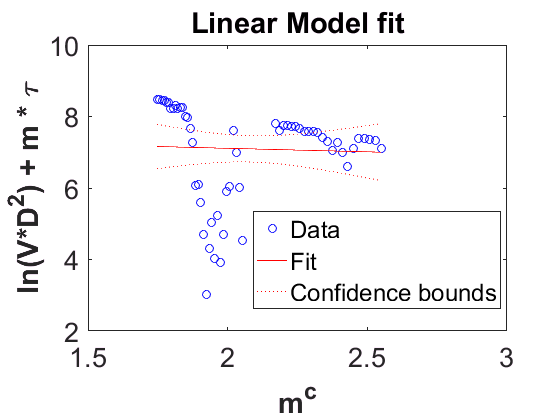

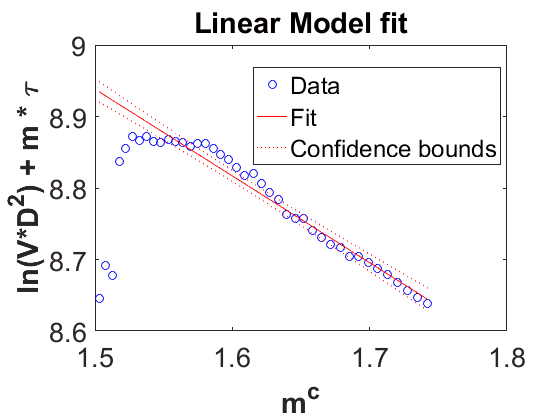

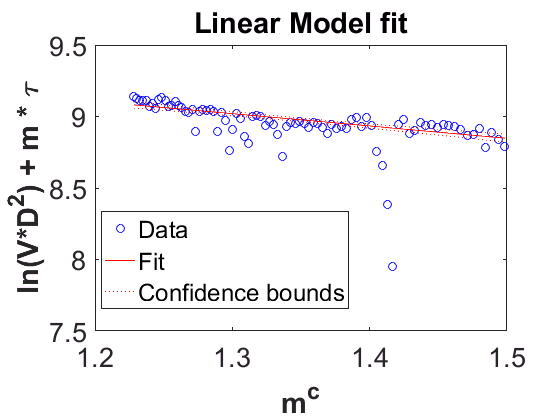

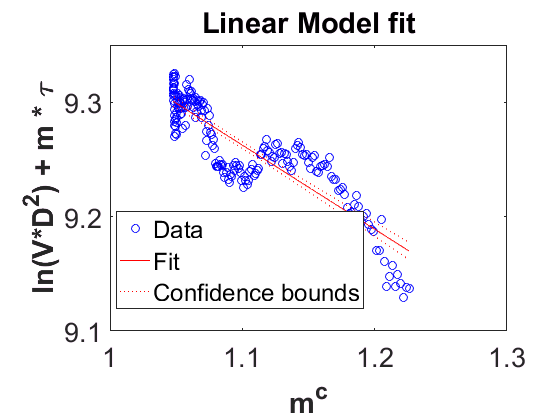

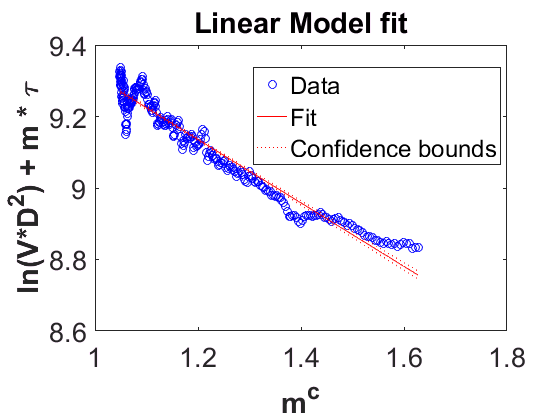


for i = 1:5
    yResponseSecond = opticalDepth * aer_940_nm(i);
    yResponse(:,i) = logResponse_940 + yResponseSecond;
end
xPredictor = opticalDepth.^(c);



    summaryCell2 = cell(5,6);
    % predictedReflectance = zeros(size(solarFiltered,1),7);
    % fitting regression line for the each band 
    betahat = zeros(8,7);
    x = 1:5;
    for i = x
        % Entering all the data into the table for the linear fit
        lineFitTable = table(yResponse(subset(i).a,i),xPredictor(subset(i).a));
        lineFitTable.Properties.VariableNames = {'yResponse','xPredictor'};
        model  = fitlm(lineFitTable,'yResponse ~ xPredictor','Robust','on');
        % coefficients of the linear fit 
        [coeffrow ,~] = size(model.Coefficients.Estimate);
        betahat(1:coeffrow,band) = model.Coefficients.Estimate;
        
      
        figure 
        plot(model,'Marker','o');
        titleText = strcat('Linear Model fit');
        title(titleText)
        xlabel('m^{c}','Interpreter','tex','FontWeight','Bold');
        ylabel('ln(V*D^{2}) + m * \tau','Interpreter','tex','FontWeight','Bold');
        ax = gca;
        ax.FontSize = 20;
        

       
        
        % Displaying the model fit statistics 
        disp(strcat('#######################################################'));
        textValue = strcat('Model ' , num2str(i)); 
        warning(textValue);
        disp(model)
        
        %{
        H0: The relationship assumed in the model is reasonable, i.e., there is no lack of fit.
        HA: The relationship assumed in the model is not reasonable, i.e., there is lack of fit.
        %}
        
        % analysis of variance 
        anova(model,'summary')
        
        disp(strcat('#######################################################'));
        
        summaryCell2(i,:) = {x(i); model.Rsquared.Ordinary*100; ...
            model.Rsquared.Adjusted*100; model.RMSE*100; model.Coefficients.Estimate(1); ...
            model.Coefficients.Estimate(2)}; 
        
    end

    summaryTable2 = cell2table(summaryCell2);
   clear summaryCell2
    summaryTable2.Properties.VariableNames = {'section', 'Rsquared', ...
        'AdjustedRsquared', 'RMSE','Intercept','Slope'};

## Water content

water = (abs(summaryTable2.Slope)/a).^(1/b)

water =     0.1238
    2.9285
    1.6073
    1.2222
    1.6989
